close("all"); clear; clc;
setmadsympath;

t = sym('t');
N = Frame;
O = Point;

yaw = DynamicVariable("psi");
camber = DynamicVariable("gamma");
pitch = DynamicVariable("theta");
tilt = sym('mu',{'real','positive'});

eul = [
    yaw;
    camber;
    pitch
    ];

Ny = N.orientNew('z',yaw.state);
Nc = Ny.orientNew('x',camber.state);
Np = Nc.orientNew('y',pitch.state);
Nt = Np.orientNew('y',tilt);
Nb = Nt.orientNew('xy',[-pi/2,pi/2]);

px = DynamicVariable('x');
py = DynamicVariable('y');
pz = DynamicVariable('z');

rb = [
    px.state;
    py.state;
    pz.state
    ];

Ob = O.locateNew(rb);

tr = sym('t_r',{'real','positive'});
rr = sym('rho_r',{'real','positive'});
h = sym('h_c',{'real','positive'});
p = sym('p',{'real','positive'});

Or = Ob.locateNew(-(h - rr).*Np.z - p.*Np.x);
Oc = Or.locateNew(-rr.*Nc.z - tr.*Ny.z);
rc = simplify(expand(posFrom(Oc)));
pprint(rc);

$$\left[\begin{array}{c} x-c_{\psi }\,c_{\theta }\,p-c_{\psi }\,h_{c}\,s_{\theta }+c_{\psi }\,\rho_{r}\,s_{\theta }-\rho_{r}\,s_{\gamma }\,s_{\psi }-c_{\theta }\,h_{c}\,s_{\gamma }\,s_{\psi }+c_{\theta }\,\rho_{r}\,s_{\gamma }\,s_{\psi }+p\,s_{\gamma }\,s_{\psi }\,s_{\theta }\\ y-c_{\theta }\,p\,s_{\psi }+c_{\psi }\,\rho_{r}\,s_{\gamma }-h_{c}\,s_{\psi }\,s_{\theta }+\rho_{r}\,s_{\psi }\,s_{\theta }+c_{\psi }\,c_{\theta }\,h_{c}\,s_{\gamma }-c_{\psi }\,c_{\theta }\,\rho_{r}\,s_{\gamma }-c_{\psi }\,p\,s_{\gamma }\,s_{\theta }\\ z-t_{r}-c_{\gamma }\,\rho_{r}-c_{\gamma }\,c_{\theta }\,h_{c}+c_{\gamma }\,c_{\theta }\,\rho_{r}+c_{\gamma }\,p\,s_{\theta } \end{array}\right]$$

C = rc(3);

wx = DynamicVariable('omega_x');
wy = DynamicVariable('omega_y');
wz = DynamicVariable('omega_z');
vx = DynamicVariable('v_x');
vy = DynamicVariable('v_y');
vz = DynamicVariable('v_z');

u = [
    wx;
    wy;
    wz;
    vx;
    vy;
    vz
    ];

V = Twist(Pose(Nb,Ob)).vector;

eqnsk = u.state - V;

q = [
    yaw;
    camber;
    pitch;
    px;
    py;
    pz
    ];

[Mk,fk] = massMatrixForm(eqnsk,q.state);
Mk = simplify(expand(Mk));
fk = simplify(expand(fk));
sys = simplify(expand(Mk\fk));

pprint(sys);

$$\left[\begin{array}{c} -\frac{\omega_{y}\,\cos\left(\mu +\theta \right)+\omega_{z}\,\sin\left(\mu +\theta \right)}{c_{\gamma }}\\ \omega_{z}\,\cos\left(\mu +\theta \right)-\omega_{y}\,\sin\left(\mu +\theta \right)\\ \frac{c_{\mu }\,c_{\theta }\,\omega_{y}\,s_{\gamma }-c_{\gamma }\,\omega_{x}+c_{\mu }\,\omega_{z}\,s_{\gamma }\,s_{\theta }+c_{\theta }\,\omega_{z}\,s_{\gamma }\,s_{\mu }-\omega_{y}\,s_{\gamma }\,s_{\mu }\,s_{\theta }}{c_{\gamma }}\\ c_{\gamma }\,s_{\psi }\,v_{x}-c_{\mu }\,c_{\psi }\,s_{\theta }\,v_{y}-c_{\psi }\,c_{\theta }\,s_{\mu }\,v_{y}-c_{\psi }\,s_{\mu }\,s_{\theta }\,v_{z}+c_{\mu }\,c_{\psi }\,c_{\theta }\,v_{z}-c_{\mu }\,c_{\theta }\,s_{\gamma }\,s_{\psi }\,v_{y}-c_{\mu }\,s_{\gamma }\,s_{\psi }\,s_{\theta }\,v_{z}-c_{\theta }\,s_{\gamma }\,s_{\mu }\,s_{\psi }\,v_{z}+s_{\gamma }\,s_{\mu }\,s_{\psi }\,s_{\theta }\,v_{y}\\ c_{\mu }\,c_{\theta }\,s_{\psi }\,v_{z}-c_{\gamma }\,c_{\psi }\,v_{x}-c_{\mu }\,s_{\psi }\,s_{\theta }\,v_{y}-c_{\theta }\,s_{\mu }\,s_{\psi }\,v_{y}-s_{\mu }\,s_{\psi }\,s_{\theta }\,v_{z}+c_{\mu }\,c_{\psi }\,c_{\theta }\,s_{\gamma }\,v_{y}+c_{\mu }\,c_{\psi }\,s_{\gamma }\,s_{\theta }\,v_{z}+c_{\psi }\,c_{\theta }\,s_{\gamma }\,s_{\mu }\,v_{z}-c_{\psi }\,s_{\gamma }\,s_{\mu }\,s_{\theta }\,v_{y}\\ c_{\gamma }\,s_{\mu }\,s_{\theta }\,v_{y}-c_{\gamma }\,c_{\mu }\,s_{\theta }\,v_{z}-c_{\gamma }\,c_{\theta }\,s_{\mu }\,v_{z}-s_{\gamma }\,v_{x}-c_{\gamma }\,c_{\mu }\,c_{\theta }\,v_{y} \end{array}\right]$$

eqnz = subs(diff(C,t),q.rate,sys);
eqnz = simplify(expand(eqnz));
eqnz = rhs(isolate(eqnz == 0,vy.state));
eqnz = simplify(expand(eqnz));
pprint(eqnz);

$$-\frac{s_{\gamma }\,v_{x}+c_{\gamma }\,c_{\theta }\,\omega_{x}\,p-c_{\mu }\,h_{c}\,\omega_{z}\,s_{\gamma }+c_{\gamma }\,h_{c}\,\omega_{x}\,s_{\theta }+c_{\gamma }\,c_{\mu }\,s_{\theta }\,v_{z}+c_{\gamma }\,c_{\theta }\,s_{\mu }\,v_{z}-c_{\mu }\,\omega_{y}\,p\,s_{\gamma }+c_{\mu }\,\omega_{z}\,\rho_{r}\,s_{\gamma }-c_{\gamma }\,\omega_{x}\,\rho_{r}\,s_{\theta }+h_{c}\,\omega_{y}\,s_{\gamma }\,s_{\mu }-\omega_{z}\,p\,s_{\gamma }\,s_{\mu }-\omega_{y}\,\rho_{r}\,s_{\gamma }\,s_{\mu }-c_{\mu }\,c_{\theta }\,\omega_{z}\,\rho_{r}\,s_{\gamma }+c_{\mu }\,\omega_{y}\,\rho_{r}\,s_{\gamma }\,s_{\theta }+c_{\theta }\,\omega_{y}\,\rho_{r}\,s_{\gamma }\,s_{\mu }+\omega_{z}\,\rho_{r}\,s_{\gamma }\,s_{\mu }\,s_{\theta }}{c_{\gamma }\,\cos\left(\mu +\theta \right)}$$


Jz = jacobian(eqnz,u.state);
Jz = simplify(expand(Jz));
eqnz = Jz*u.state;
pprint(eqnz);

$$\frac{\omega_{z}\,s_{\gamma }\,\left(c_{\mu }\,h_{c}-c_{\mu }\,\rho_{r}+p\,s_{\mu }+\rho_{r}\,\cos\left(\mu +\theta \right)\right)}{c_{\gamma }\,\cos\left(\mu +\theta \right)}-\frac{\omega_{x}\,\left(c_{\theta }\,p+h_{c}\,s_{\theta }-\rho_{r}\,s_{\theta }\right)}{\cos\left(\mu +\theta \right)}-\frac{s_{\gamma }\,v_{x}}{c_{\gamma }\,\cos\left(\mu +\theta \right)}-\frac{v_{z}\,\sin\left(\mu +\theta \right)}{\cos\left(\mu +\theta \right)}+\frac{\omega_{y}\,s_{\gamma }\,\left(c_{\mu }\,p-h_{c}\,s_{\mu }+\rho_{r}\,s_{\mu }-\rho_{r}\,\sin\left(\mu +\theta \right)\right)}{c_{\gamma }\,\cos\left(\mu +\theta \right)}$$


params = [
    tilt;
    tr;
    rr;
    p;
    h
    ].';

q = prettify(eul.state).';
u = prettify(u.state).';
f = prettify(eqnz);

f = matlabFunction(f,'Vars',{q,u,params});
clearvars -except f;

speed = 130;
results_path = "G:\My Drive\BikeSimResults\BigSports\Chicane";
speed_path = "\Vx" + num2str(speed) + "Kph\";
file_name = "bikesim_results_" + num2str(speed) + "kph.csv";
ref = readtable(results_path + speed_path + file_name);

yaw = deg2rad(ref.Yaw);
pitch = deg2rad(ref.Pitch);
roll = deg2rad(ref.Roll_E);

R = angle2dcm(yaw,pitch,roll);
[yaw,camber,pitch] = dcm2angle(R,'ZXY');

q = [yaw,camber,pitch];

tform = rigidtform3d(rotx(90).'*roty(90),[0,0,0]);

wx = ref.AVx_S1;
wy = ref.AVy_S1;
wz = ref.AVz_S1;
w = deg2rad([wx,wy,wz]);
w = transformPointsInverse(tform,w);

vx = ref.Vx_S1;
vy = ref.Vy_S1;
vz = ref.Vz_S1;
v = [vx,vy,vz]./3.6;

v = transformPointsInverse(tform,v);

u = [w,v];

tilt = deg2rad(20);
p = 1.37 - 0.0896;
h = 0.9098;
Rr = 0.297;
tr = 70E-03;
rr = Rr - tr;

params = [
    tilt;
    tr;
    rr;
    p;
    h
    ].';

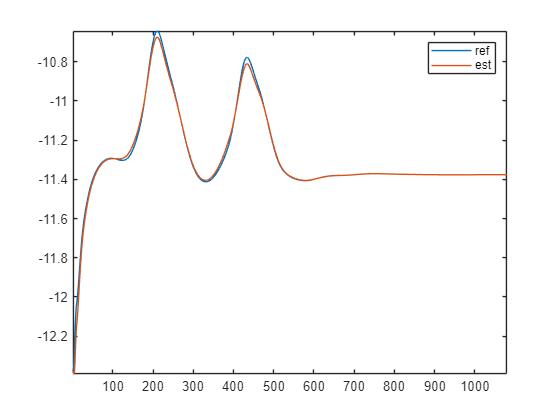

figure;
hold on;
plot(u(:,5));
plot(f(q,u,params));
hold off;
axis tight;
box on;
legend('ref','est');